## Reconstruction of Attractor

### 1、Losgistic

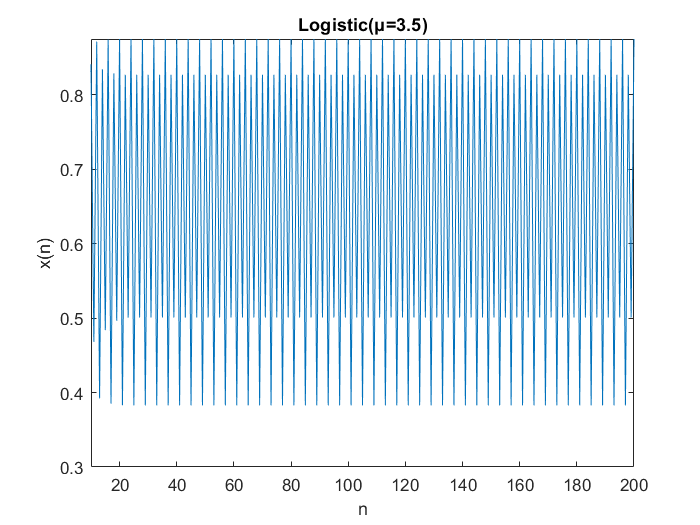

clc
clear
n = 200;
x = zeros(n,1);
u = 3.5;
x(1) = 0.3;
for i = 1:n
x(i+1) =u*x(i) * (1-x(i));
end
figure('Name','Logistic','NumberTitle','off')
plot(1:length(x),x)
xlabel('n')
ylabel('x(n)')
title(['Logistic(μ=' num2str(u) ')' ])
axis([10 200 -inf inf])

### Losgistic Bifurcation

Logistic映射的分岔图，会随u的取值不同出现不同的情况: 

当初值x在0-1间时，u在0-1时只有稳定零解，1-3周期1，3-3.449周期2，3.449-3.556周期倍增，之后混沌。

意义：1、所有点都聚集在一个点附近，或者在某个点不动 2、所有点聚集在若干点附近或不出现聚集或收敛的情况。

方法：解方程不断迭代，求得稳定的点绘制在图上

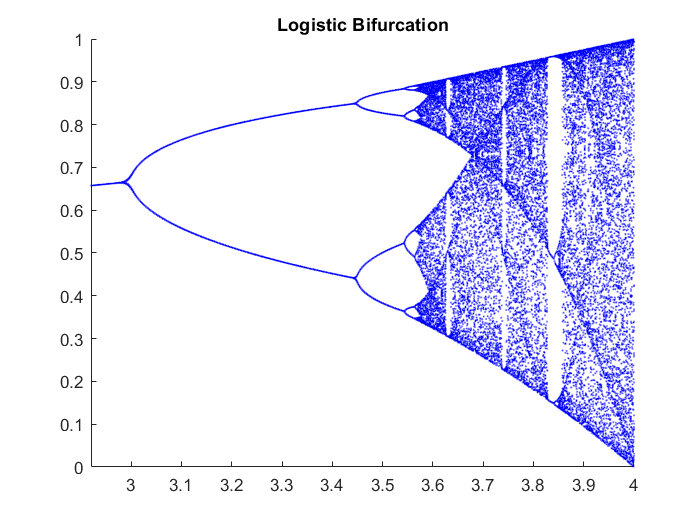

figure()
axis([2.92,4,0,1]);
title('Logistic Bifurcation');
hold on
for u= 1:0.001:4;%u从1增加到4，步长0.001
x(1)= 0.1;
r(1)=u;
    for i =1:250
    x(i+1) = u *x(i) *(1-x(i));
    r(i)=u;
    end
plot(r(200:250),x(200:250),'b.','MarkerSize',0.5);
end
hold off

### 2、Lorenz

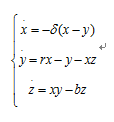

Time Series

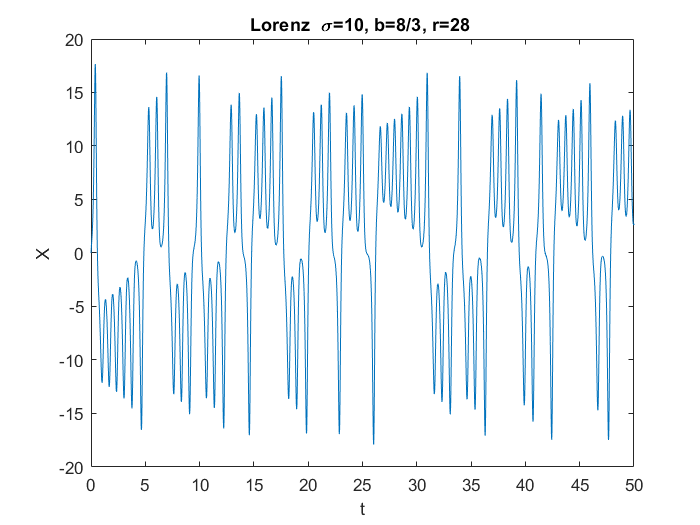

%Lorenz，rung（funciton，【ragne】，【initial】，accurancy）
a=0;
b=200;
c=[0 2 9];
h=0.01;
[t,y]=rung(@lorenz,[a b],c,h);

% X
figure("Name",'X')
plot(t,y(1,:))
xlim([0 50])
title('Lorenz  \sigma=10, b=8/3, r=28 ')
xlabel('t')
ylabel('X')

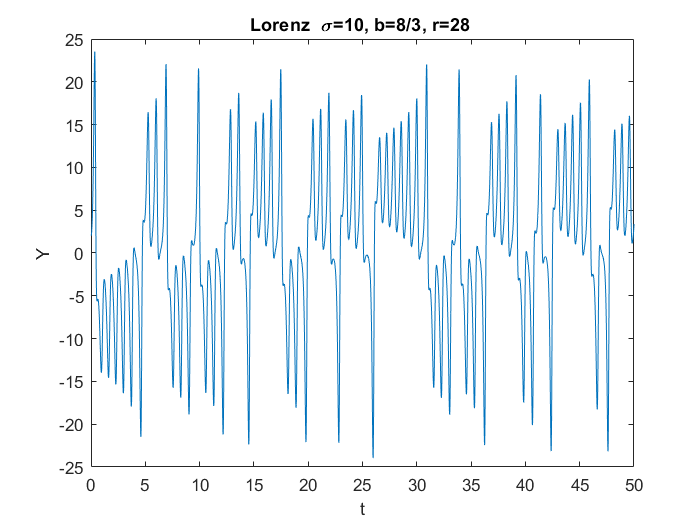


% Y
figure("Name",'Y')
plot(t,y(2,:))
xlim([0 50])
title('Lorenz  \sigma=10, b=8/3, r=28 ')
xlabel('t')
ylabel('Y')

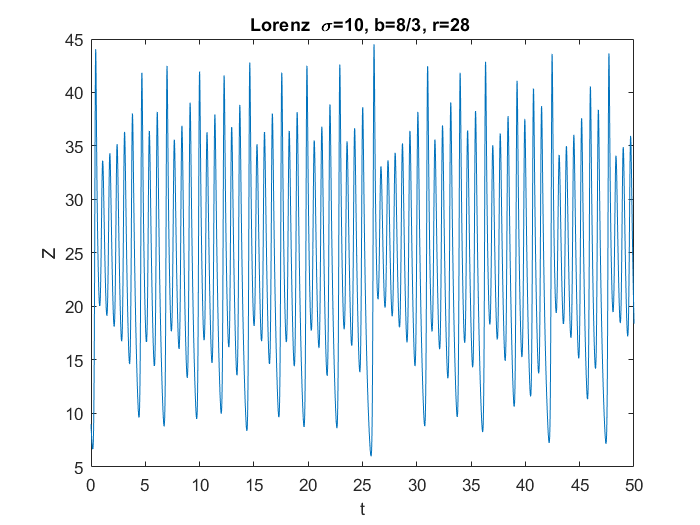


% Z
figure("Name",'Z')
plot(t,y(3,:))
xlim([0 50])
title('Lorenz  \sigma=10, b=8/3, r=28 ')
xlabel('t')
ylabel('Z')

Attractor

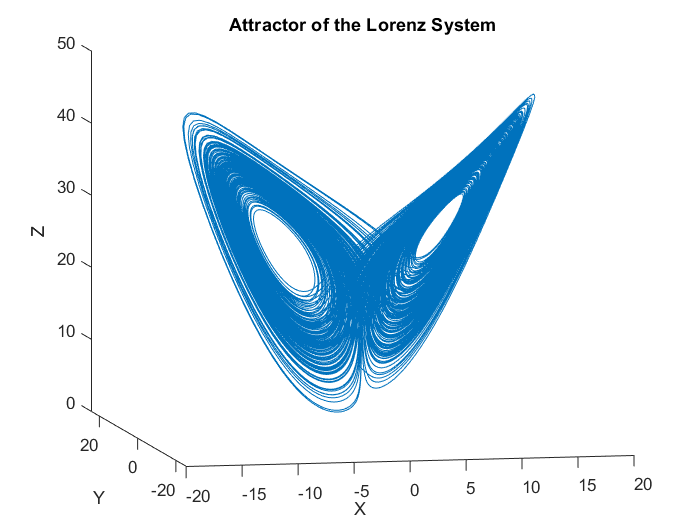

figure("Name",'Attractor')
plot3(y(1,:), y(2,:), y(3,:))
view(-12,9)
title("Attractor of the Lorenz System")
xlabel('X')
ylabel('Y')
zlabel('Z')

3、陈 System

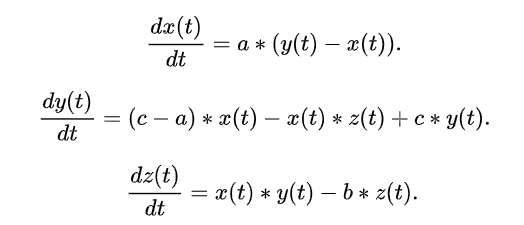

a = 40, c = 28, b = 3

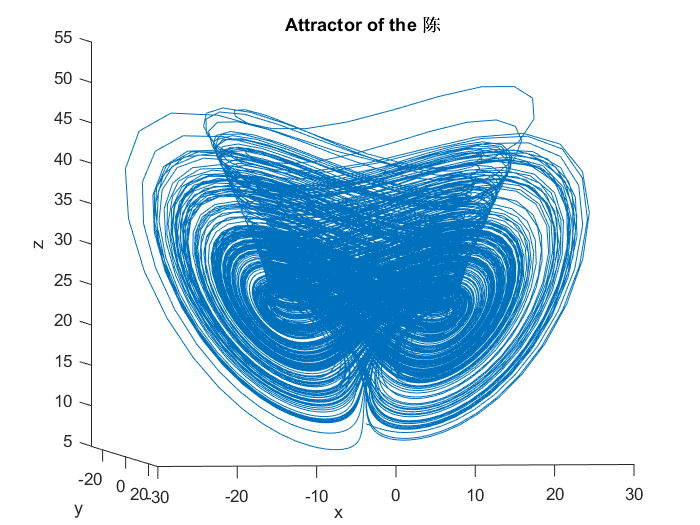

a=0;
b=200;
c=[0 2 9];
h=0.01;
[t,y]=rung(@Chen,[a b],c,h);

plot3(y(1,:),y(2,:),y(3,:))
xlabel('x')
ylabel('y')
zlabel('z')
title('Attractor of the 陈')
view(8,-3)